# **RS-HL-10: Time Variant MDP Functions**

**Oden Institute**

**Hongseok Kim**

**7/11/2024**

## Scope

- In this report, the function module and input/output analysis of Time Variant MDP of Satellite Simulation is Presented.

## I. Call the SAT-to-SAT Dataset

clear;clc;
% Load the Satellite Contat Dataset
addpath('Desktop/Redstone_Project/RS_HL/RS_HL_10_TV_MDP_Functions/')
load('/workspace/RS_Dataset/RS_HL_3_dataset.mat')

## II. Run MDP

time_index_vector = 1:20;

destination_state = 38;

MDP = runMDP(sat_to_sat_contact_3d_matrix, time_index_vector,destination_state);

simulation set up complete! 
Policy: 1 -> Value Iteration: 435
Policy: 2 -> Value Iteration: 13
Policy: 3 -> Value Iteration: 8
Policy: 4 -> Value Iteration: 5
Policy: 5 -> Value Iteration: 6
Policy: 6 -> Value Iteration: 7
Policy: 7 -> Value Iteration: 7
Policy: 8 -> Value Iteration: 6
Policy: 9 -> Value Iteration: 3
Policy: 10 -> Value Iteration: 4
Policy: 11 -> Value Iteration: 3
Policy: 12 -> Value Iteration: 1


### II.6 Test

start_time = 1;
start_state = 20;

time_index = start_time:max(time_index_vector);

simulation_time = length(time_index);

state_list = zeros(simulation_time,1);
reward_list = zeros(simulation_time,1);
cumulative_reward = 0;

state_list(1) = start_state;

% We should consider the possibility of the failure (80% success and 20%
% failure)

for t = 1:simulation_time
    current_state = state_list(t);

    pi_dist = MDP.(['time' num2str(time_index(t))]).('policy_distribution');
    action_number = find(pi_dist(current_state,:));

    if length(action_number) > 1
        action_number = randsample(action_number,1);
    end

    next_state = MDP.(['time' num2str(time_index(t))]).(['state' num2str(current_state)]).(['action' num2str(action_number)]).('success').('next_state');
    reward = MDP.(['time' num2str(time_index(t))]).(['state' num2str(current_state)]).(['action' num2str(action_number)]).('success').('reward');
    cumulative_reward = cumulative_reward + reward;

    reward_list(t+1) = cumulative_reward;
    state_list(t+1) = next_state;
end

[state_list, reward_list]

ans =     20     0
    41   -15
    40   -16
    39   -17
    38    83
    38    83
    38    83
    38    83
    38    83
    38    83


## III.Analysis

### III.1 State Value changing over time

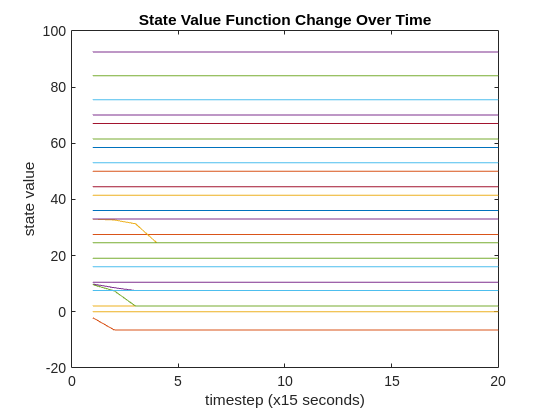

number_of_states = length(sat_to_sat_contact_3d_matrix(1,:,1));
state_value_over_time = zeros(length(time_index_vector),number_of_states);

for t = 1:length(time_index_vector)
    for state_index = 1:number_of_states
        state_value_over_time(t,state_index) = MDP.(['time' num2str(time_index_vector(t))]).(['state' num2str(state_index)]).('state_value');            
    end
end

for state_index = 1:number_of_states
    plot(time_index_vector,state_value_over_time(:,state_index))
    hold on
end

hold off
title('State Value Function Change Over Time')
xlabel('timestep (x15 seconds)')
ylabel('state value')